## The blackbody problem

Notice that as you increase the temperature of the body, the emittance at high frequencies does not increase. Why is that?

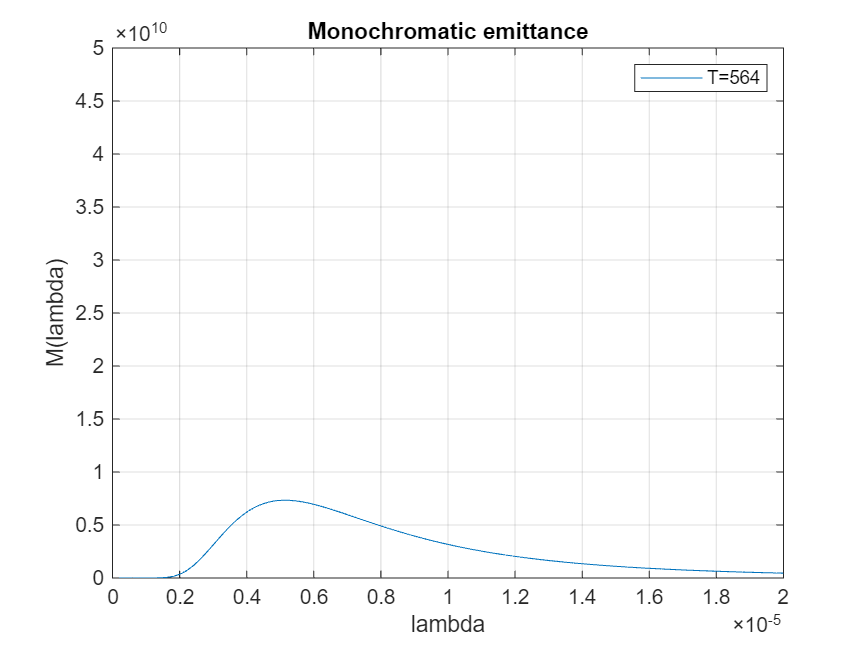

clear;
c0 = 2.997e8;      % m/s speed of light in vaccum
h = 6.625*10e-34;  % J.s Planck constant 
k = 1.38*10e-23;   % T/K Boltzmann constant
n = 1;             % Refractive index of the medium         


T = 564;

lambda = linspace(0, 2e-5, 100); 
Mi=(2*pi.*h.*(c0.^2))./((n.^2).*(lambda.^5).*(exp((h.*c0)./(n.*k.*lambda.*T))-1));
plot(lambda, Mi)
grid
xlabel('lambda')
ylabel('M(lambda)')
title('Monochromatic emittance')
legend("T=" + T);
ylim([0 5e10])